Let's assume for a **simply supported beam**, Load, P follows a normal distibution with mean 50kN, standard deviation of 12kN. Location of load, X, follows a uniform distribution between 0m and 12m. If you are doing this for a different structure or load distrubution, you may need to change some parts of this code! It is up to you to find what parts!

close all; clear all; clc; 
L=12; % length of the beam
N=10000; %number of sampling points (should be a "large" number)
%You may need to change these if you are using different variables with
%different distributions!

% Load,x P follows a normal distibution with mean 50kN, standard deviation of 12kN
Pdist='Normal'; meanp=50; stdp=12; %because normal, we need mean and stdev
pdf_p=@(p) pdf(Pdist,p,meanp,stdp); %probability distribution function for P
P=random(Pdist,meanp,stdp,[N,1]); %we want N random samples from this distribution 

% Location of load, x, follows a uniform distribution between 0m and 12m
Xdist='Uniform'; xlow=0; xhigh=12; %because uniform, we need the bounds
pdf_x=@(x) pdf(Xdist,x,xlow,xhigh); %probability distribution function for X
X=random(Xdist,xlow,xhigh,[N,1]); %we want N random samples from this distribution 

%Maximum moment for a simply supported beam
%If you are doing different structures, you have to change this function!
Moment=@(p,x) p.*x-p.*x.^2./(L);

How do we visualize these distibutions? What do P and X look like? We can sample them and then plot a histogram! P should look "normal", X should look "uniform". Congrats! You learned how to do Monte-Carlo simulations. You may show off to your friends.

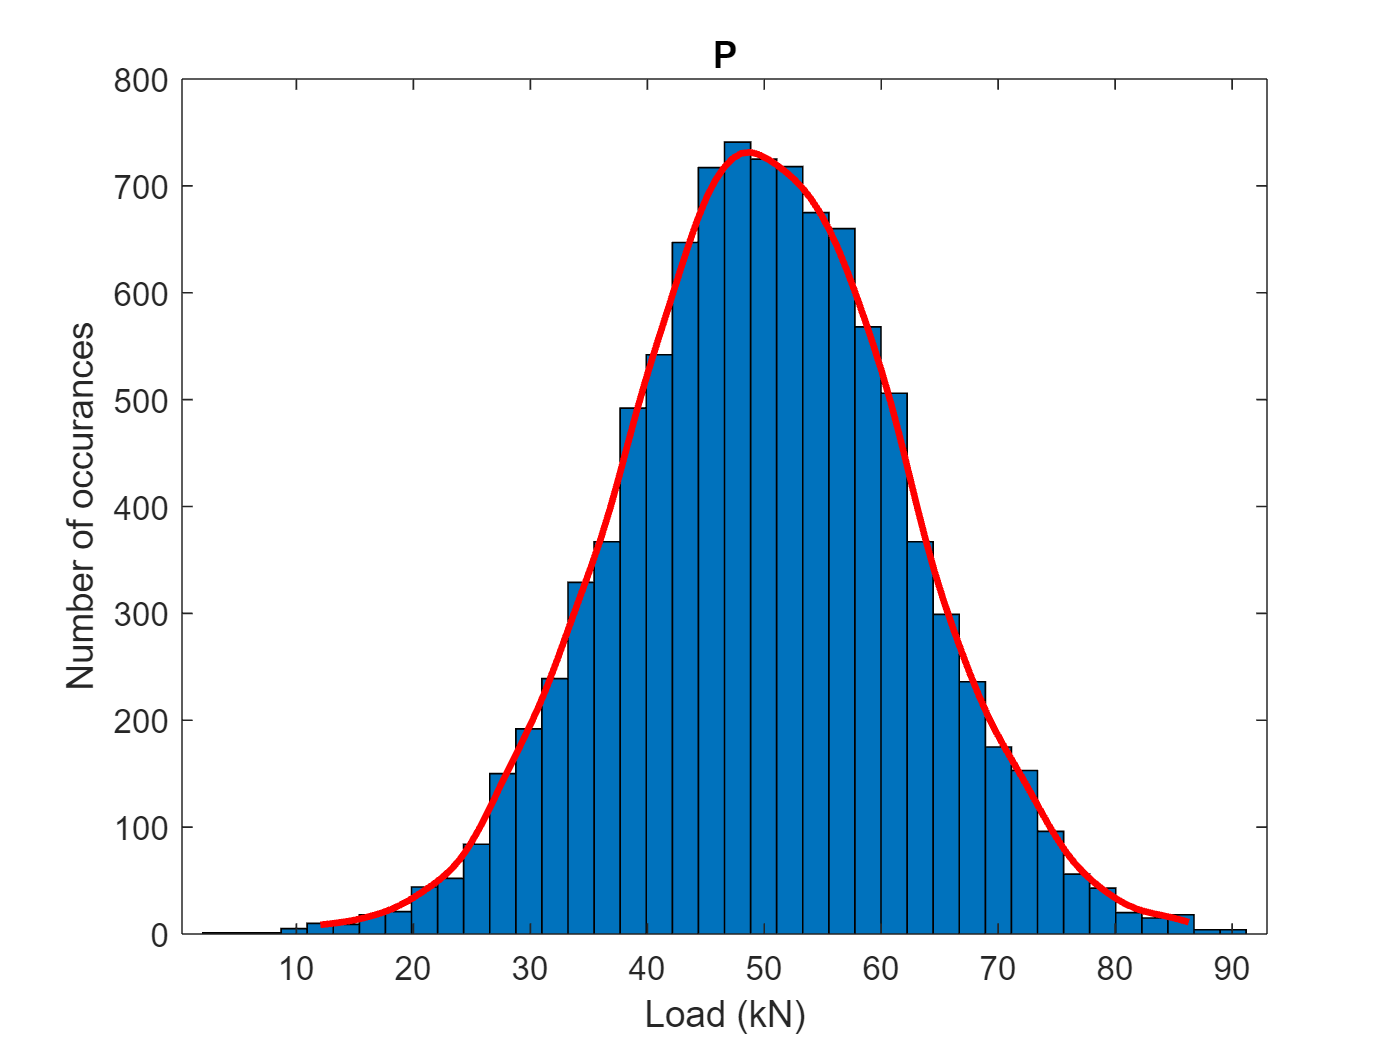

%Let's make sure they follow these distributions by plotting their
%histograms after sampling them 5000 times, 

% For Load, P
figure();
histfit(P,40,'kernel'); %Should Look Normal
xlabel('Load (kN)'); ylabel('Number of occurances'); title('P');

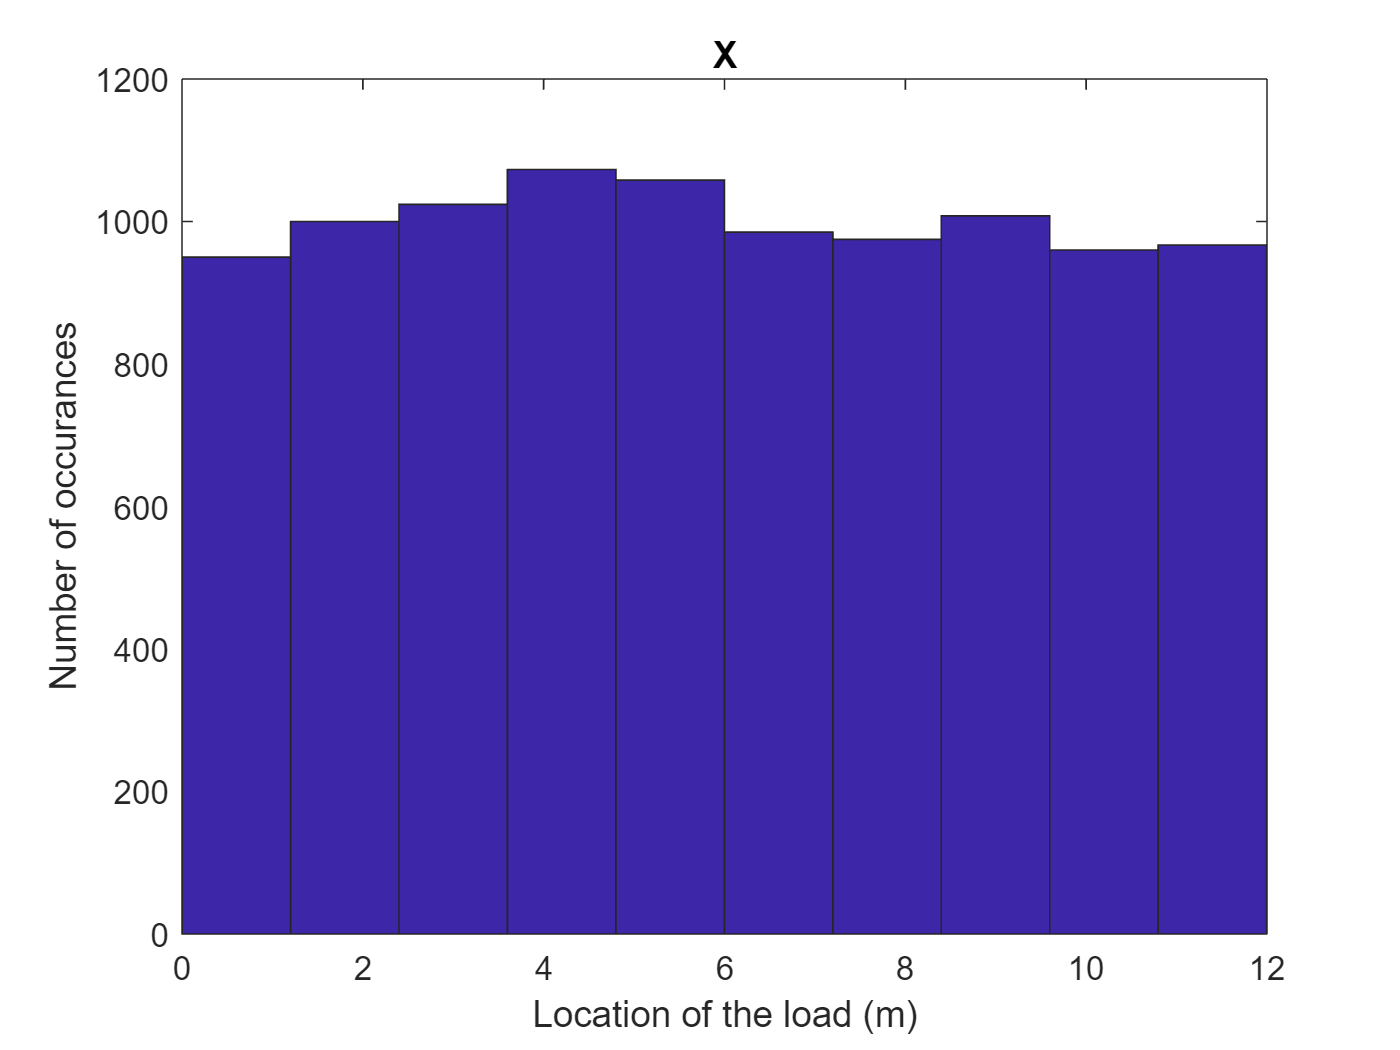


%Location, x
figure();
hist(X); %Should look uniform
xlabel('Location of the load (m)'); ylabel('Number of occurances'); title('X');

Time to calculate mean moment assuming independent load and location. Please recall, for a **simply support beam**, maximum moment is **P*x-P*x^2/L. **This is not true for all systems! Remember, mean should be 25/3*L=100kN*m for our case.

funct=@(p,x) Moment(p,x).*pdf_p(p).*pdf_x(x);
%Integrate twice to find the mean
%technically these bounds should be infinite for normal dist! But we have numerical problems
%For uniform they are bounds. You may need to change these
Mean_Moment=integral2(funct,meanp-10*stdp,meanp+10*stdp,xlow,xhigh,'method','iterated') 

Mean_Moment = 100.0000


%Now lets calculate the moment of mean_x and mean_p E[P]*E[x]-E[P]*E[x]^2/L
%This may be different than Mean_Moment! It is a first order approximation
Moment_of_means=Moment(meanp,(xhigh+xlow)/2)

Moment_of_means = 150

Now let's calculate our results from the sample. This should be almost equal to actual mean moment

Approx_Mean_Moment=mean(Moment(P,X))

Approx_Mean_Moment = 100.7815

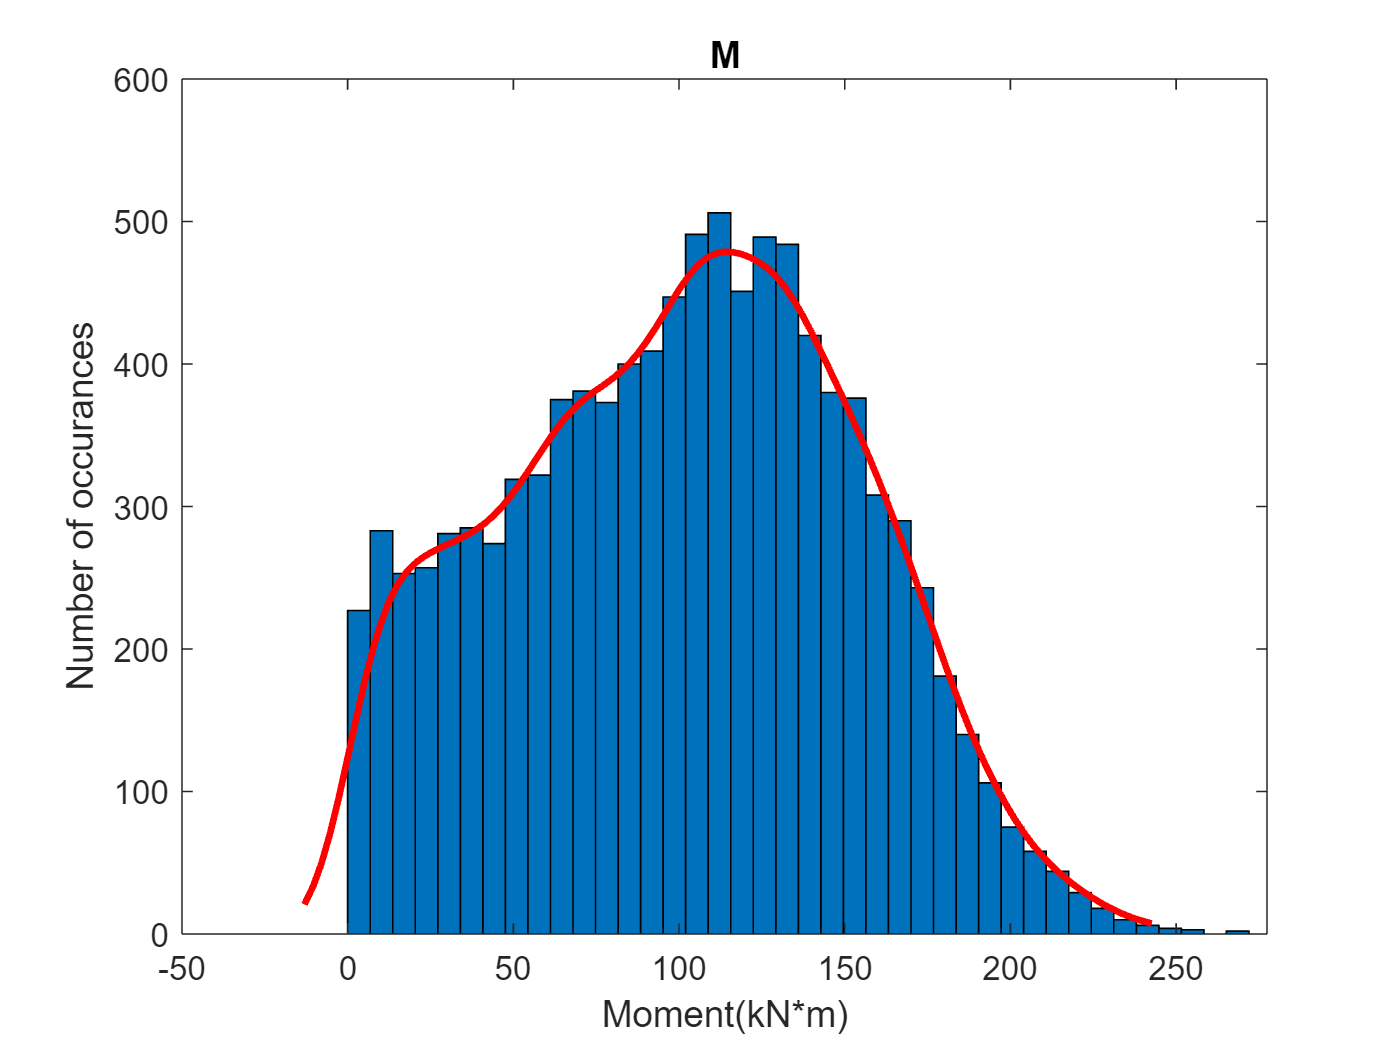

figure();
histfit(Moment(P,X),40,'kernel'); %Distribution of Moment
xlabel('Moment(kN*m)'); ylabel('Number of occurances'); title('M');

Let's assume the **section fails if moment exceeds 150kNm**, what is the probability of that happening? We can just look at our samples

prob_fail=sum(Moment(P,X)>150)/N*100 %in percentage

prob_fail = 18.7300